## Different Types of Transducers and their Frequency Range

- **The linear transducer for 2D imaging has a wide footprint and its central frequency is 2.5Mhz – 12Mhz**

- **The linear transducer for 3D imaging has a wide footprint and a central frequency of 7.5Mhz – 11Mhz**

- **The convex transducer for 2D imaging has a wide footprint and its central frequency is 2.5MHz – 7.5MHz**

- **The convex transducer for 3D imaging has a wide field of view and a central frequency of 3.5MHz – 6.5MHz.**

- **Phased Array transducer has a small footprint and low frequency (its central frequency is 2Mhz – 7.5Mhz)**

## Transducer Frequency Effect on Resolution

- ** Lower frequencies produce greater resolution but are limited in depth penetration.**

- **Higher frequencies produce greater resolution, but depth of penetration is limited**

### **This is a MATLAB script that simulates the acoustic pressure field generated by an L11-5v, L12-3v, C5-2V, P4-2V ultrasound  transducer at different frequencies and with different attenuation coefficients.**

- **The script sets up a loop to iterate through a range of frequencies specified in the freq vector and for each frequency, it sets the transducer center frequency (fc) to the current frequency value.**

- ** It then calculates the time delays for each element of the transducer array using the txdelay function, and computes the pressure field generated by the transducer using the pfield function.**

- ** The pressure field is then plotted using the imagesc and colorbar functions,  and the positions of the transducer elements are  overlaid on the plot using the plot function.**

- **The script then repeats these steps for each frequency in the freq vector, with the attenuation coefficient set to 0.5 dB/cm/MHz for the second plot.**

- **In general, increasing the frequency of an ultrasound transducer can lead to a decrease in the RMS acoustic pressure field. This is because higher frequency sound waves have shorter wavelengths, which can cause them to be absorbed more easily  by the medium through which they propagate, resulting in a decrease in the intensity of the acoustic pressure field. **

### **Effect of Attenuation coefficient on the pressure field with the selected frequency.**

- **The attenuation coefficient is a measure of how much the ultrasound wave is attenuated (i.e., weakened) as it propagates through the tissue. The higher the attenuation coefficient, the greater the amount of energy that  is lost as the wave travels through the tissue.**

- **In this code, when the attenuation coefficient is set to 0.5 dB/cm/MHz, the pressure field calculations performed by the 'pfield' function take into account this attenuation effect. Specifically, the function applies an attenuation factor to the pressure field at each point in the grid, which reduces the amplitude of the pressure waves as they propagate through the tissue. As a result, the resulting image will be darker overall, since the pressure amplitudes are lower due to the attenuation.**

- **In practice, attenuation can have a significant impact on ultrasound imaging, since it affects the ability of the ultrasound waves to penetrate through the tissue and reach deeper structures. By simulating the effect of attenuation in this code, it is possible to explore how different attenuation coefficients might impact the quality and clarity of the resulting ultrasound images.**

-  **In general, the attenuation coefficient is measured in units of dB/cm/MHz, and can range from less than 0.1 dB/cm/MHz for some fluids to more than 3 dB/cm/MHz for dense tissues like bone.**

param = struct with fields:
           fc: 12000000
         kerf: 3.0000e-05
        width: 2.7000e-04
        pitch: 3.0000e-04
    Nelements: 128
    bandwidth: 77
       radius: Inf
       height: 0.0050
        focus: 0.0180


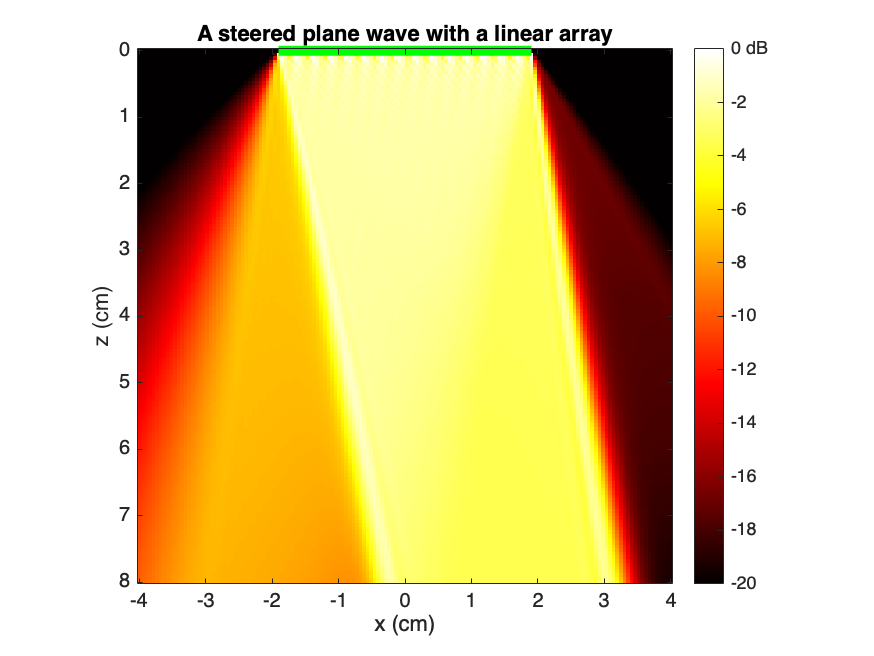

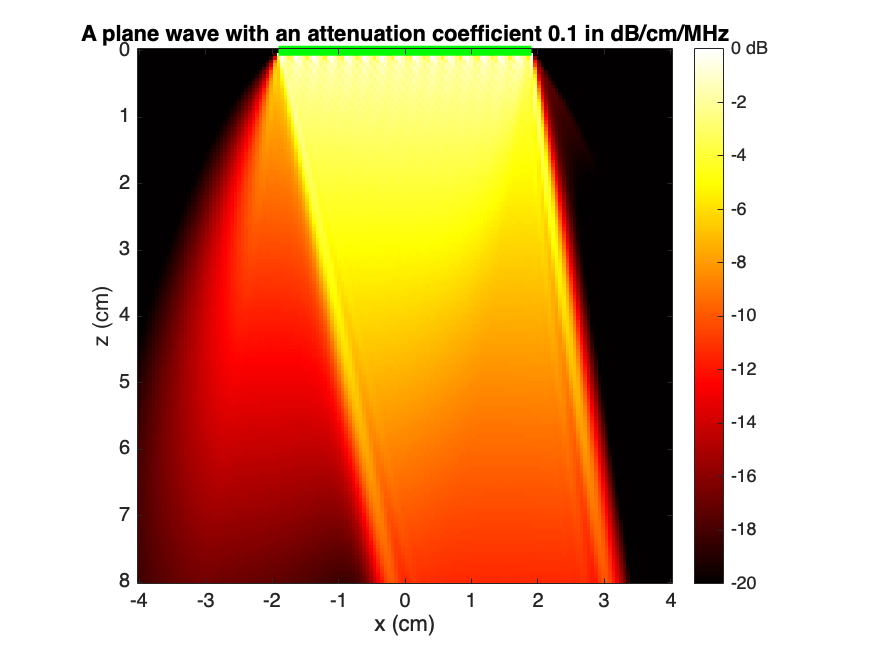

param = struct with fields:
             fc: 10600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


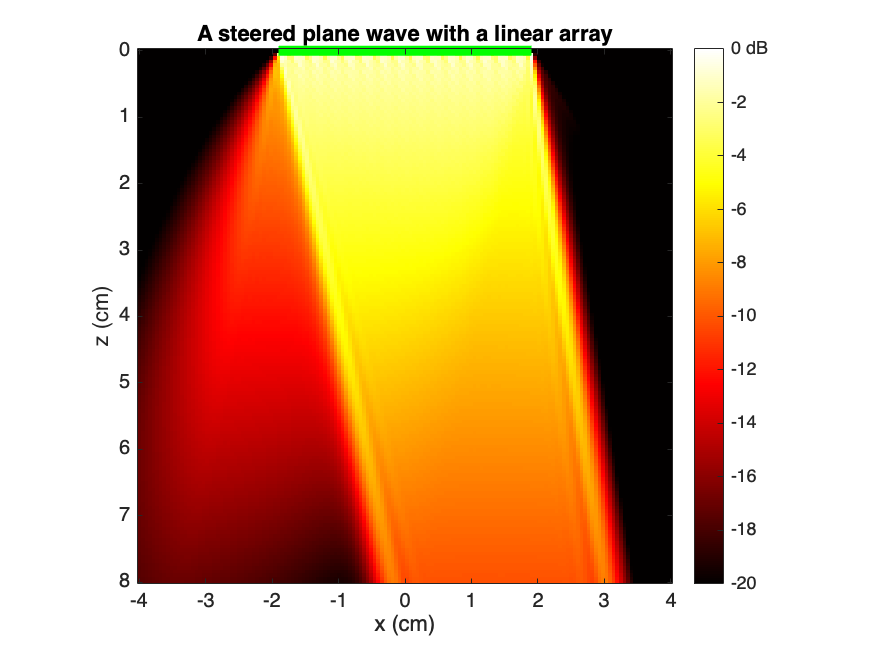

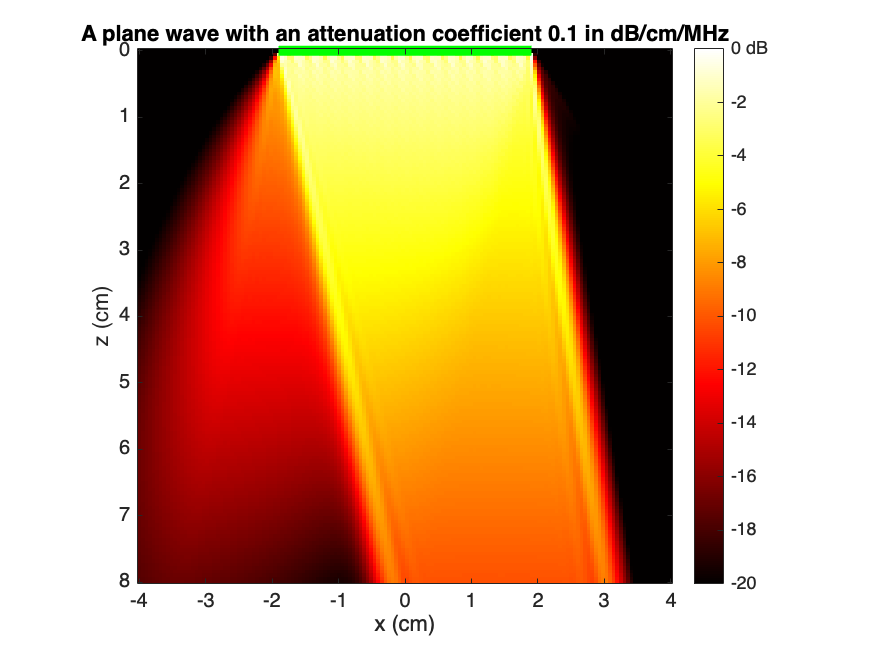

param = struct with fields:
             fc: 8500000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


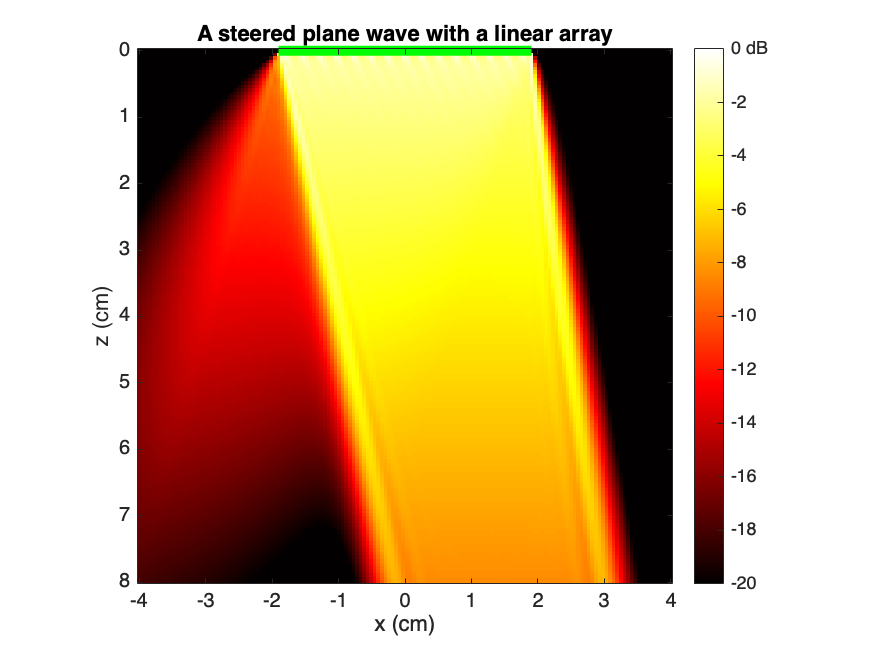

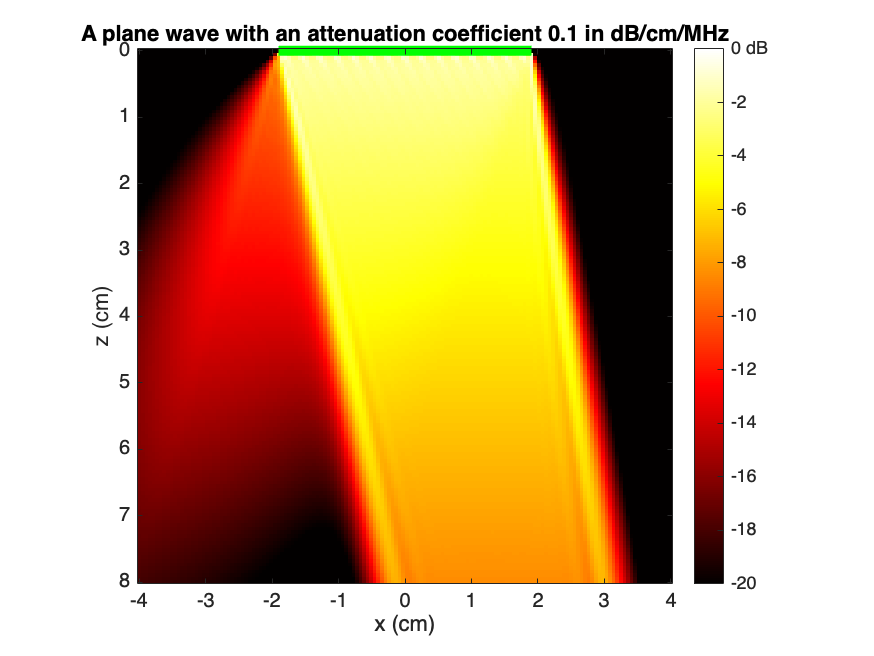

param = struct with fields:
             fc: 7600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


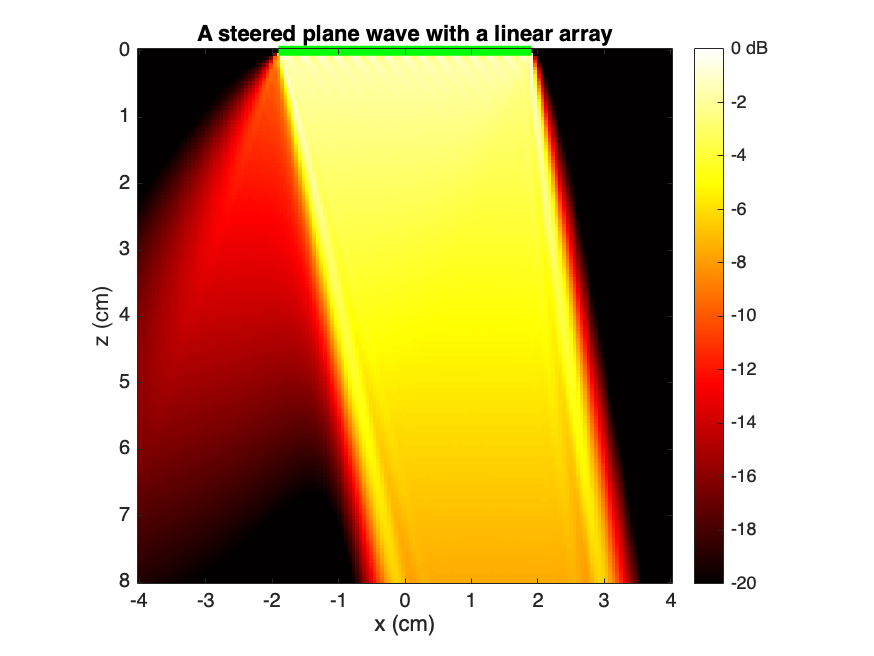

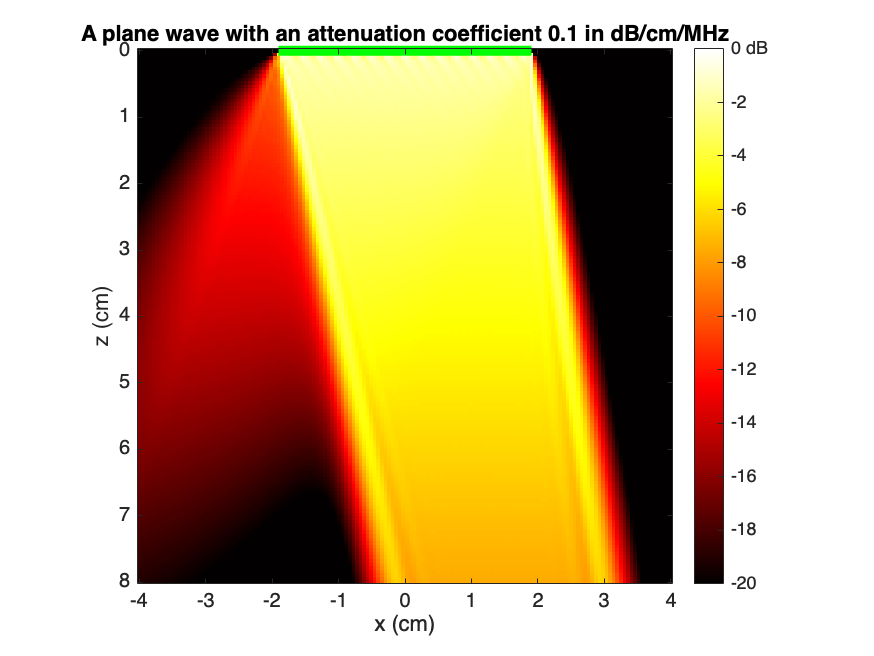

param = struct with fields:
             fc: 3400000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


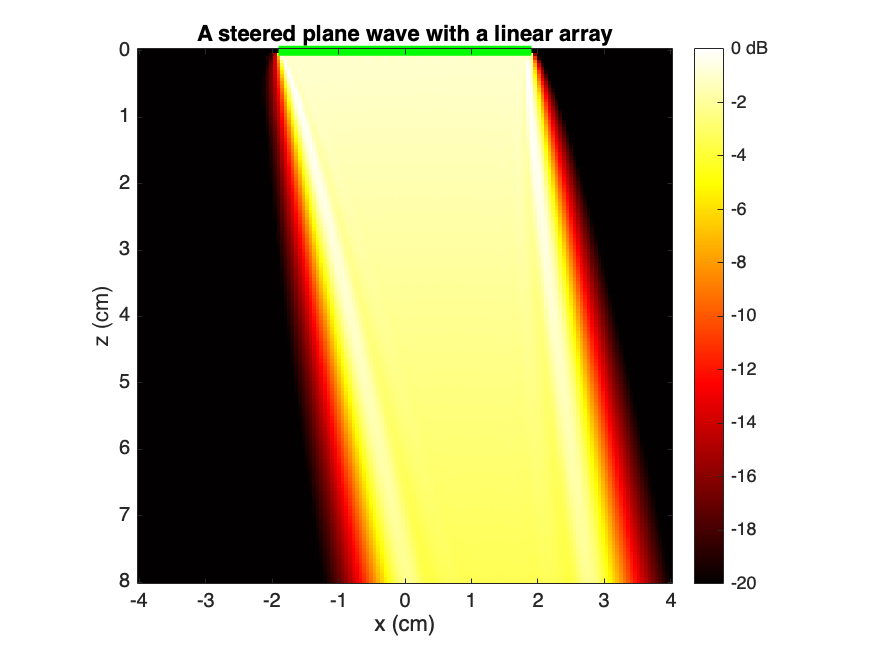

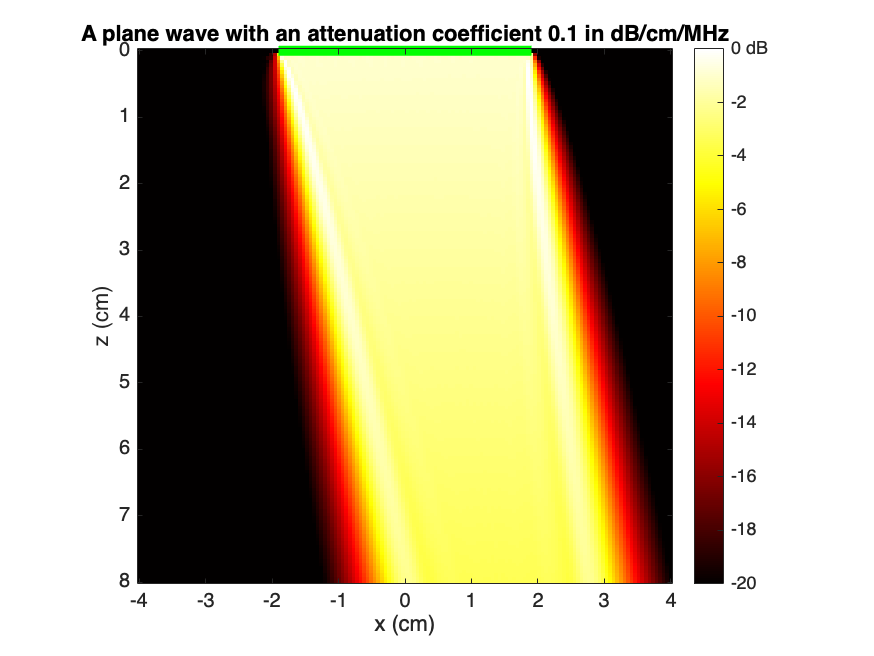

param = struct with fields:
             fc: 2500000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


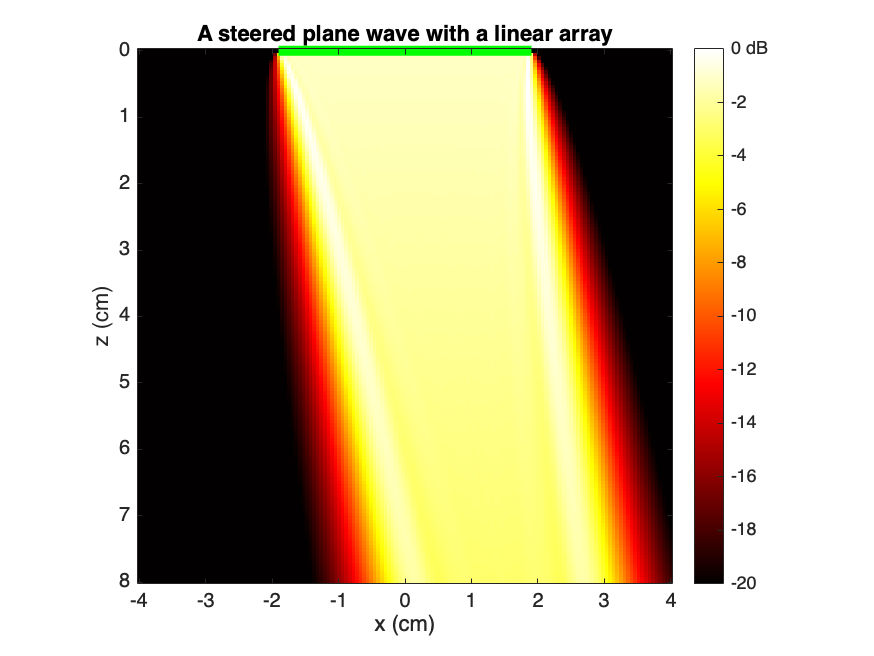

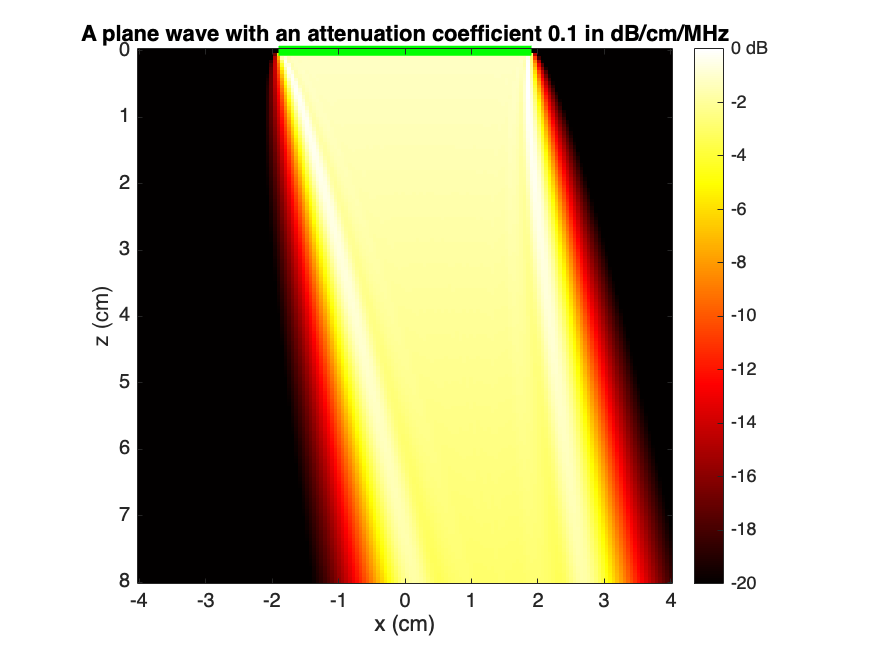

param = struct with fields:
             fc: 450000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.1000


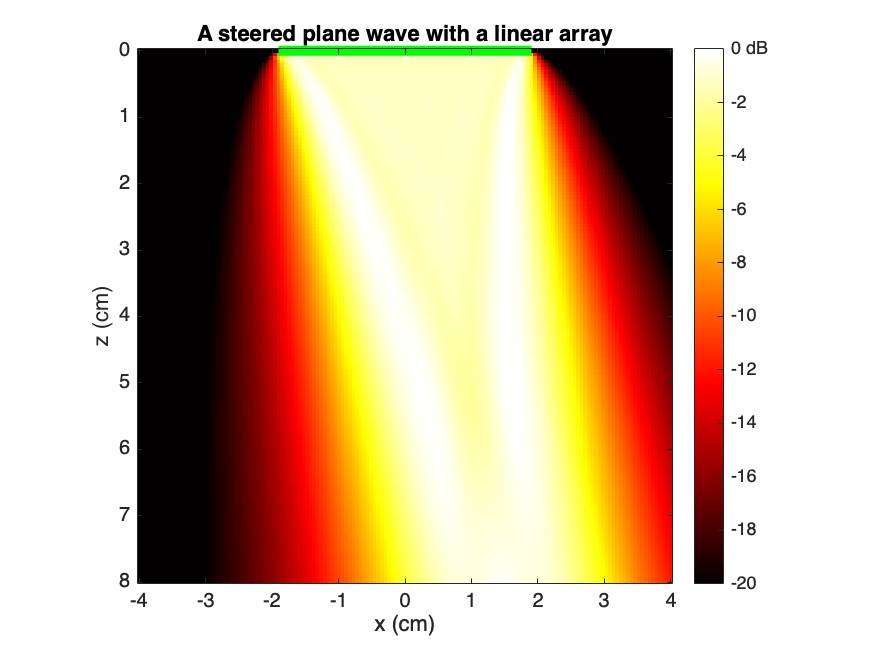

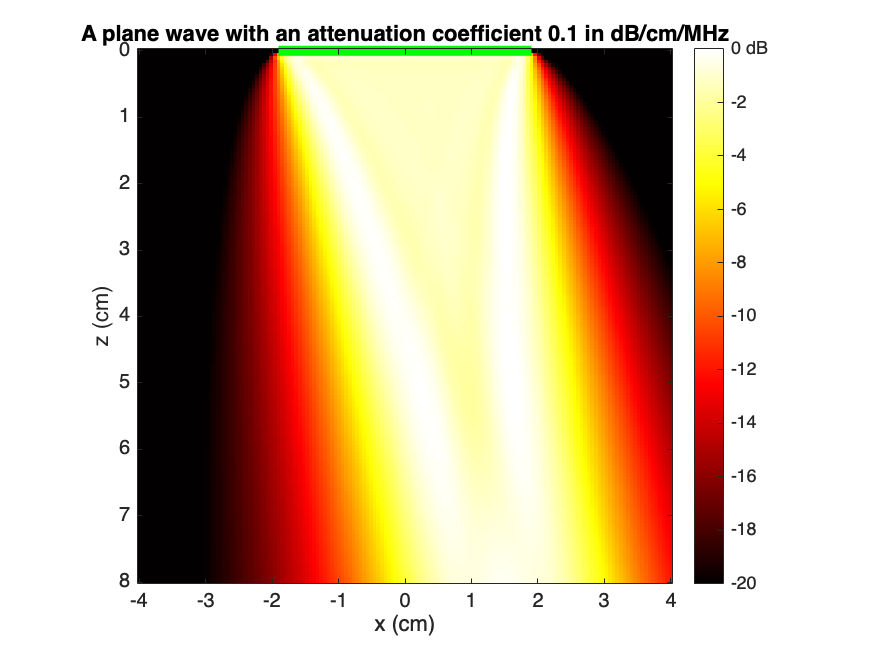


   
param = getparam('L11-5v');

freq_linear = [12e6,10.6e6,8.5e6, 7.6e6, 3.4e6, 2.5e6, 4.5e5]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 0.1;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB

    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 0.1 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end
